# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
%sid = SIDS{8}
for i = 8:length(SIDS)-4
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
            typeCell = {'180'};
            
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = [];
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
                
                lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
                vecType = repmat(typeCell{i},lengthType,1);
                vecTypeC = cellstr(vecType)';
                anovaType = [anovaType{:} vecTypeC];
                typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
                anovaTotalMags = [anovaTotalMags typeResp];
                num5S = repmat('Ct>=5',length(tempResp3),1);
                num3S= repmat('3<=Ct<=4',length(tempResp2),1);
                num1S = repmat('1<=Ct<=2',length(tempResp1),1);
                numBaseS = repmat('Base',length(tempBase),1);
                
                %             numNullS = repmat('Null',length(tN),1);
                
                b5C = cellstr(num5S)';
                b3C = cellstr(num3S)';
                b1C = cellstr(num1S)';
                BC = cellstr(numBaseS)';
                %             nC = cellstr(numNullS)';
                anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        %         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
    %     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
    %     [c,m,h,gnames] = multcompare(stats);
    
end

sid = ecb43e

p =     0.0000
    0.3742
       NaN


tbl =     'Source'                                   'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'         'Prob>F'    
    'anovaNumStims(anovaType,anovaBetaSID)'    [1.2670e+04]    [   9]    [        0]    [1.4077e+03]    [5.7173]    [8.3393e-08]
    'anovaType(anovaBetaSID)'                  [  484.4114]    [   2]    [        0]    [  242.2057]    [0.9837]    [    0.3742]
    'anovaBetaSID'                             [         0]    [   0]    [        0]    [         0]    [     0]    [       NaN]
    'Error'                                    [3.1714e+05]    [1288]    [        0]    [  246.2261]          []              []
    'Total'                                    [3.3055e+05]    [1299]    [        0]              []          []              []


stats =          source: 'anovan'
          resid: [1300×1 double]
         coeffs: [17×1 double]
            Rtr: [12×12 double]
       rowbasis: [12×17 double]
            dfe: 1288
            mse: 246.2261
    nullproject: [17×12 double]
          terms: [3×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [4×1 double]
     coeffnames: {17×1 cell}
           vars: [17×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: [3×3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


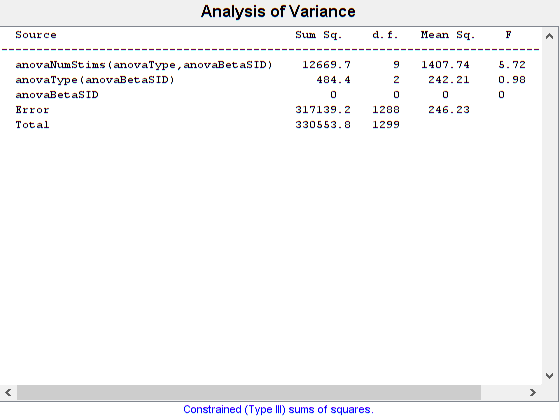

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

p =     0.2315
       NaN


tbl =     'Source'                     'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'         'Prob>F'
    'anovaType(anovaBetaSID)'    [  744.8811]    [   2]    [        0]    [372.4405]    [1.4647]    [0.2315]
    'anovaBetaSID'               [         0]    [   0]    [        0]    [       0]    [     0]    [   NaN]
    'Error'                      [3.2981e+05]    [1297]    [        0]    [254.2860]          []          []
    'Total'                      [3.3055e+05]    [1299]    [        0]            []          []          []


stats =          source: 'anovan'
          resid: [1300×1 double]
         coeffs: [5×1 double]
            Rtr: [3×3 double]
       rowbasis: [3×5 double]
            dfe: 1297
            mse: 254.2860
    nullproject: [5×3 double]
          terms: [2×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [3×1 double]
     coeffnames: {5×1 cell}
           vars: [5×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: [2×2 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


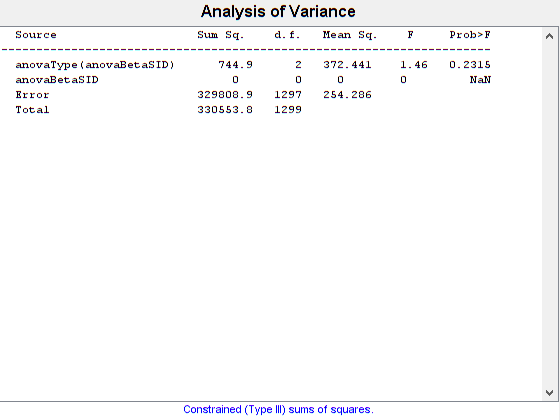

[p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])

p =     0.0000
    0.3742
       NaN
    0.4952
       NaN
       NaN
       NaN


tbl =     'Source'                                  'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims'                           [1.1167e+04]    [   3]    [        0]    [3.7223e+03]    [15.1174]    [1.1313e-09]
    'anovaType'                               [  484.4114]    [   2]    [        0]    [  242.2057]    [ 0.9837]    [    0.3742]
    'anovaBetaSID'                            [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType'                 [1.3273e+03]    [   6]    [        0]    [  221.2118]    [ 0.8984]    [    0.4952]
    'anovaNumStims*anovaBetaSID'              [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaType*anovaBetaSID'                  [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType*anovaBetaSID'    [         0]    [   0]    [        0]    [   

stats =          source: 'anovan'
          resid: [1300×1 double]
         coeffs: [40×1 double]
            Rtr: [12×12 double]
       rowbasis: [12×40 double]
            dfe: 1288
            mse: 246.2261
    nullproject: [40×12 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {40×1 cell}
           vars: [40×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


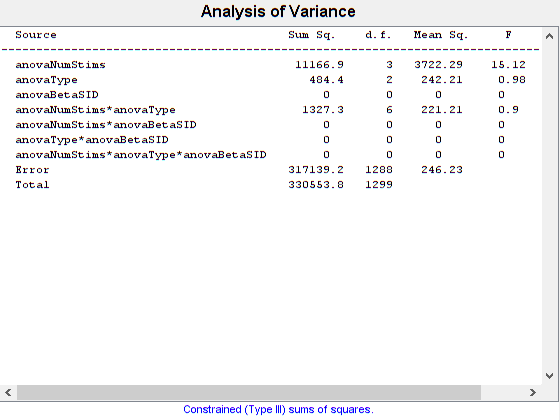

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'model','full','varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

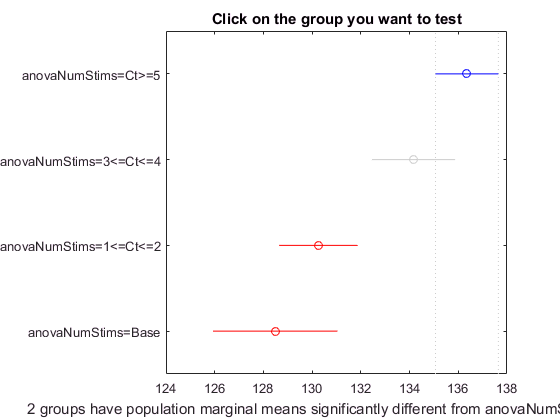

c =     1.0000    2.0000   -0.7987    2.1946    5.1879    0.2351
    1.0000    3.0000    3.2216    6.0988    8.9760    0.0000
    1.0000    4.0000    3.9915    7.8692   11.7469    0.0000
    2.0000    3.0000    0.5516    3.9042    7.2568    0.0147
    2.0000    4.0000    1.4322    5.6746    9.9171    0.0033
    3.0000    4.0000   -2.3909    1.7704    5.9317    0.6938


m =   136.3554    0.6741
  134.1609    0.9504
  130.2566    0.8944
  128.4862    1.3505


h =   Figure (5: Multiple comparison of population marginal means) with properties:

      Number: 5
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'



%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType},'varnames',{'anovaNumStims','anovaType'},'model','full

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [136.3554]    [0.6741]
    'anovaNumStims=3<=Ct<=4'    [134.1609]    [0.9504]
    'anovaNumStims=1<=Ct<=2'    [130.2566]    [0.8944]
    'anovaNumStims=Base'        [128.4862]    [1.3505]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [126 138]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [126 138]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [126 138]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


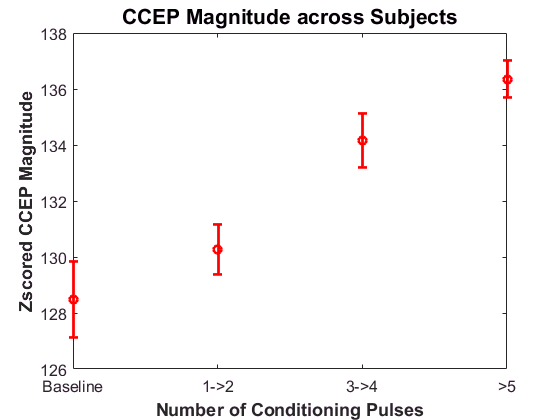

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

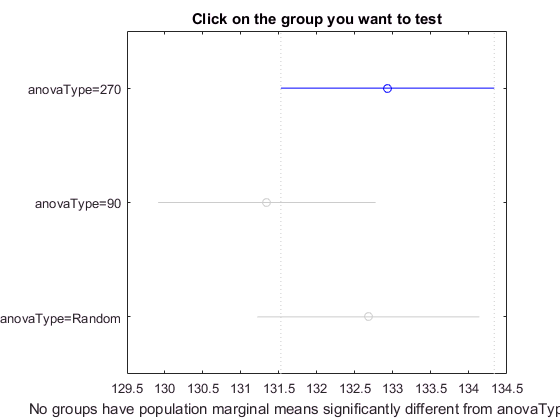

results1 =     1.0000    2.0000   -1.2453    1.5884    4.4221    0.3875
    1.0000    3.0000   -2.6117    0.2533    3.1184    0.9766
    2.0000    3.0000   -4.2272   -1.3350    1.5571    0.5253



figure
results1 = multcompare(stats,'Dimension',[2])

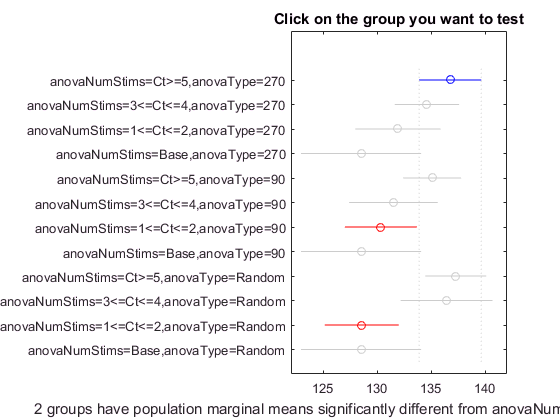

cM =     1.0000    2.0000   -3.5705    2.1503    7.8712    0.9868
    1.0000    3.0000   -2.0090    4.8436   11.6962    0.4693
    1.0000    4.0000   -0.3529    8.2546   16.8621    0.0746
    1.0000    5.0000   -3.6888    1.6717    7.0323    0.9973
    1.0000    6.0000   -1.7698    5.2563   12.2824    0.3755
    1.0000    7.0000    0.2753    6.4194   12.5636    0.0314
    1.0000    8.0000   -0.3529    8.2546   16.8621    0.0746
    1.0000    9.0000   -6.0468   -0.5156    5.0156    1.0000
    1.0000   10.0000   -6.8553    0.3332    7.5218    1.0000
    1.0000   11.0000    1.9340    8.1896   14.4451    0.0011


mM =   136.7408    1.2106
  134.5905    1.2645
  131.8972    1.7121
  128.4862    2.3392
  135.0691    1.1068
  131.4846    1.7767
  130.3214    1.4384
  128.4862    2.3392
  137.2564    1.1828
  136.4076    1.8366


hM =   Figure (8: Multiple comparison of population marginal means) with properties:

      Number: 8
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaType=270'
    'anovaNumStims=3<=Ct<=4,anovaType=270'
    'anovaNumStims=1<=Ct<=2,anovaType=270'
    'anovaNumStims=Base,anovaType=270'
    'anovaNumStims=Ct>=5,anovaType=90'
    'anovaNumStims=3<=Ct<=4,anovaType=90'
    'anovaNumStims=1<=Ct<=2,anovaType=90'
    'anovaNumStims=Base,anovaType=90'
    'anovaNumStims=Ct>=5,anovaType=Random'
    'anovaNumStims=3<=Ct<=4,anovaType=Random'
    'anovaNumStims=1<=Ct<=2,anovaType=Random'
    'anovaNumStims=Base,anovaType=Random'




% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

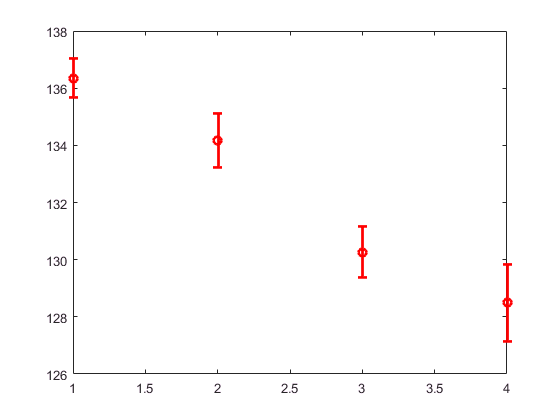



errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')


figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[2 3])

Error using multcompare (line 245)
DIM must specify only categorical factors with 2 or more degrees of freedom.



figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 3])

p = 0.0074

tbl =     'Source'    'SS'            'df'     'MS'            'F'         'Prob>F'
    'Groups'    [3.7753e+03]    [  3]    [1.2584e+03]    [4.0321]    [0.0074]
    'Error'     [1.9725e+05]    [632]    [  312.1031]          []          []
    'Total'     [2.0102e+05]    [635]              []          []          []


stats =     gnames: {4x1 cell}
         n: [88 185 265 98]
    source: 'anova1'
     means: [62.9984 57.5380 58.8454 54.2007]
        df: 632
         s: 17.6664


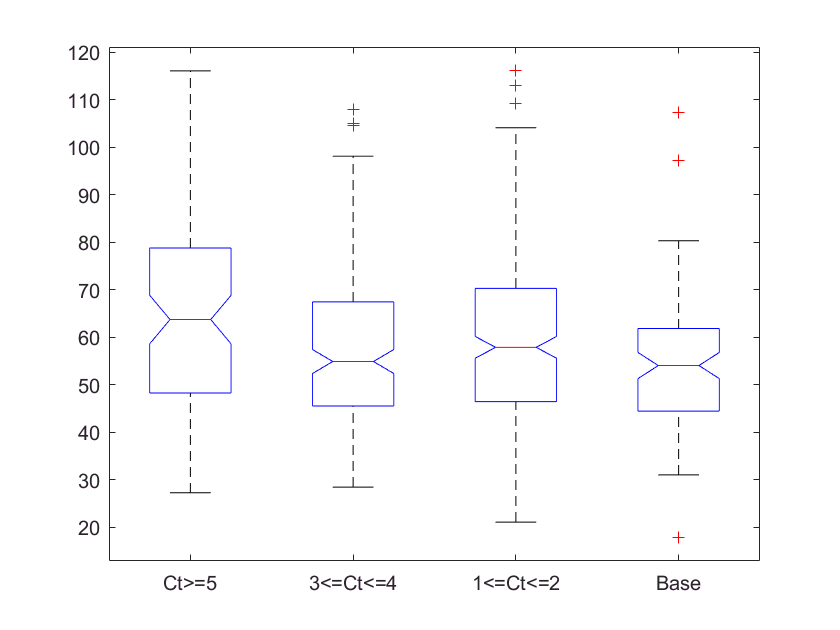

[p,tbl,stats] = anova1(anovaTotalMags,anovaNumStims)

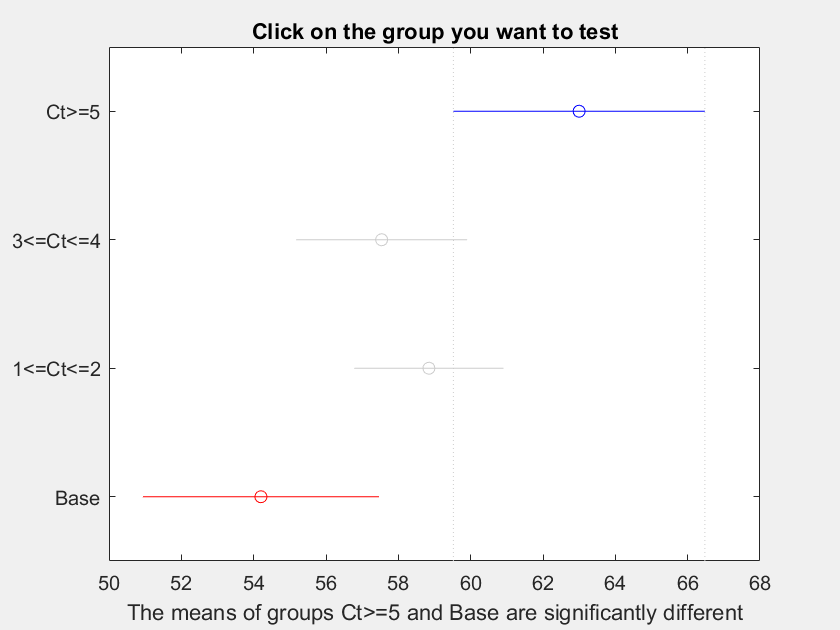

ans =     1.0000    2.0000   -0.4169    5.4604   11.3376    0.0796
    1.0000    3.0000   -1.4310    4.1530    9.7369    0.2235
    1.0000    4.0000    2.1324    8.7977   15.4630    0.0039
    2.0000    3.0000   -5.6557   -1.3074    3.0409    0.8669
    2.0000    4.0000   -2.3330    3.3374    9.0077    0.4302
    3.0000    4.0000   -0.7210    4.6448   10.0106    0.1168


multcompare(stats)